clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

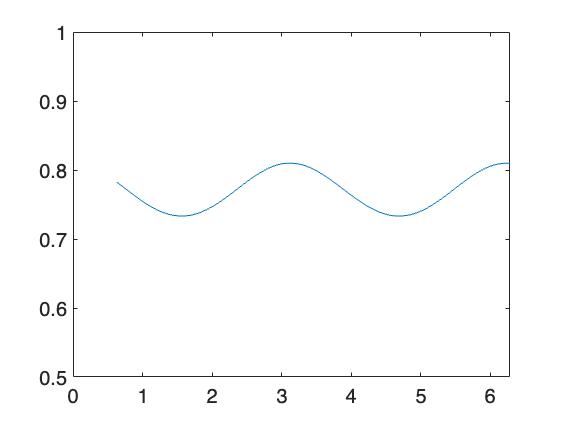

initial_0 = [0.9 0.1 0 0 0 0]';
initial = ham_evolve(sigmay,initial_0,0.1);
%initial = initial_0;
ham1 = 0.0*sigmax+1*sigmaz+0.1*sigmaz^2;
ham2 = 0*sigmax+0.2*sigmax^2;
timelist = [1:0.1:10].*pi/5;
for i = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(i));
    final_state(:,i) = ham_evolve(sigmay,precess_state,-0.1);
    %final_state(:,i) = precess_state;
end
pop_state = abs(final_state).^2;

plot(timelist,pop_state(1,:));
%ylim([0.5 1]);

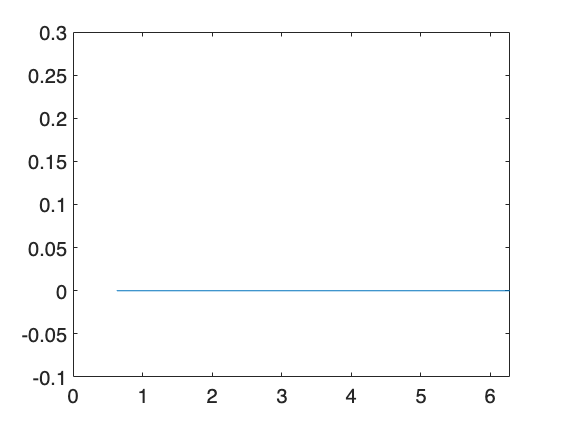

plot(timelist,pop_state(6,:));
%ylim([-0.1 0.3]);

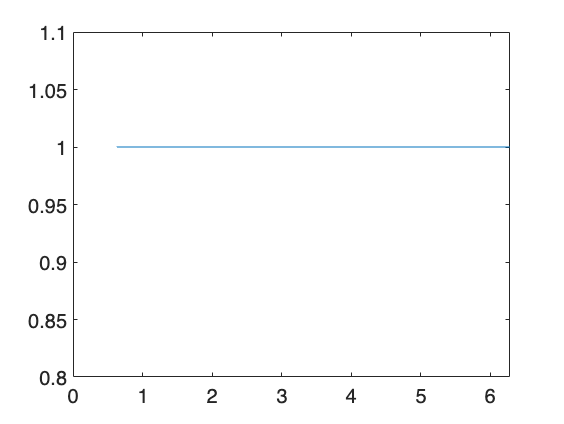

plot(timelist,(pop_state(1,:)-pop_state(6,:))./(pop_state(1,:)+pop_state(6,:)));
%ylim([0.8 1.1]);

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end